folder = "C:\Users\Nickolay\Desktop\ITMO-courses\7_term\Optimal_control_theory\lab4\tex\images\";

A = [0 1; -2 9];
B = [4; 8];
Q = [3 0; 0 2];
r = 1;
T = 5;

options = odeset('RelTol', 1e-9, 'AbsTol', 1e-11);

solP = ode45(@(t,p) riccati(t,p,A,B,Q,r), ...
    [T 0], [0; 0; 0], options);

p0 = deval(solP, 0);
P0 = [p0(1) p0(2); p0(2) p0(3)];
K0 = B.'*P0/r;

P0

P0 =     2.6761   -1.7319
   -1.7319    1.4969


K0

K0 =    -3.1508    5.0479



alpha_values = [0.5 0.75 1 1.25 1.5];
results = cell(1,5);

for i = 1:5
    alpha = alpha_values(i);

    [t, x] = ode45(@(t,x) model(t,x,solP,A,B,Q,r,alpha), ...
        [0 T], [1; 0; 0], options);

    u = zeros(length(t),1);

    for j = 1:length(t)
        p = deval(solP,t(j));
        P = [p(1) p(2); p(2) p(3)];
        K = B.'*P/r;

        u(j) = -alpha*K*x(j,1:2).';
    end

    results{i}.t = t;
    results{i}.X = x(:,1:2);
    results{i}.u = u;
    results{i}.J = x(:,3);

    fprintf("alpha = %.1f, J = %.6f\n", alpha, x(end,3));
end

alpha = 0.5, J = 3.258780
alpha = 0.8, J = 2.725568
alpha = 1.0, J = 2.676107
alpha = 1.2, J = 2.694722
alpha = 1.5, J = 2.731391


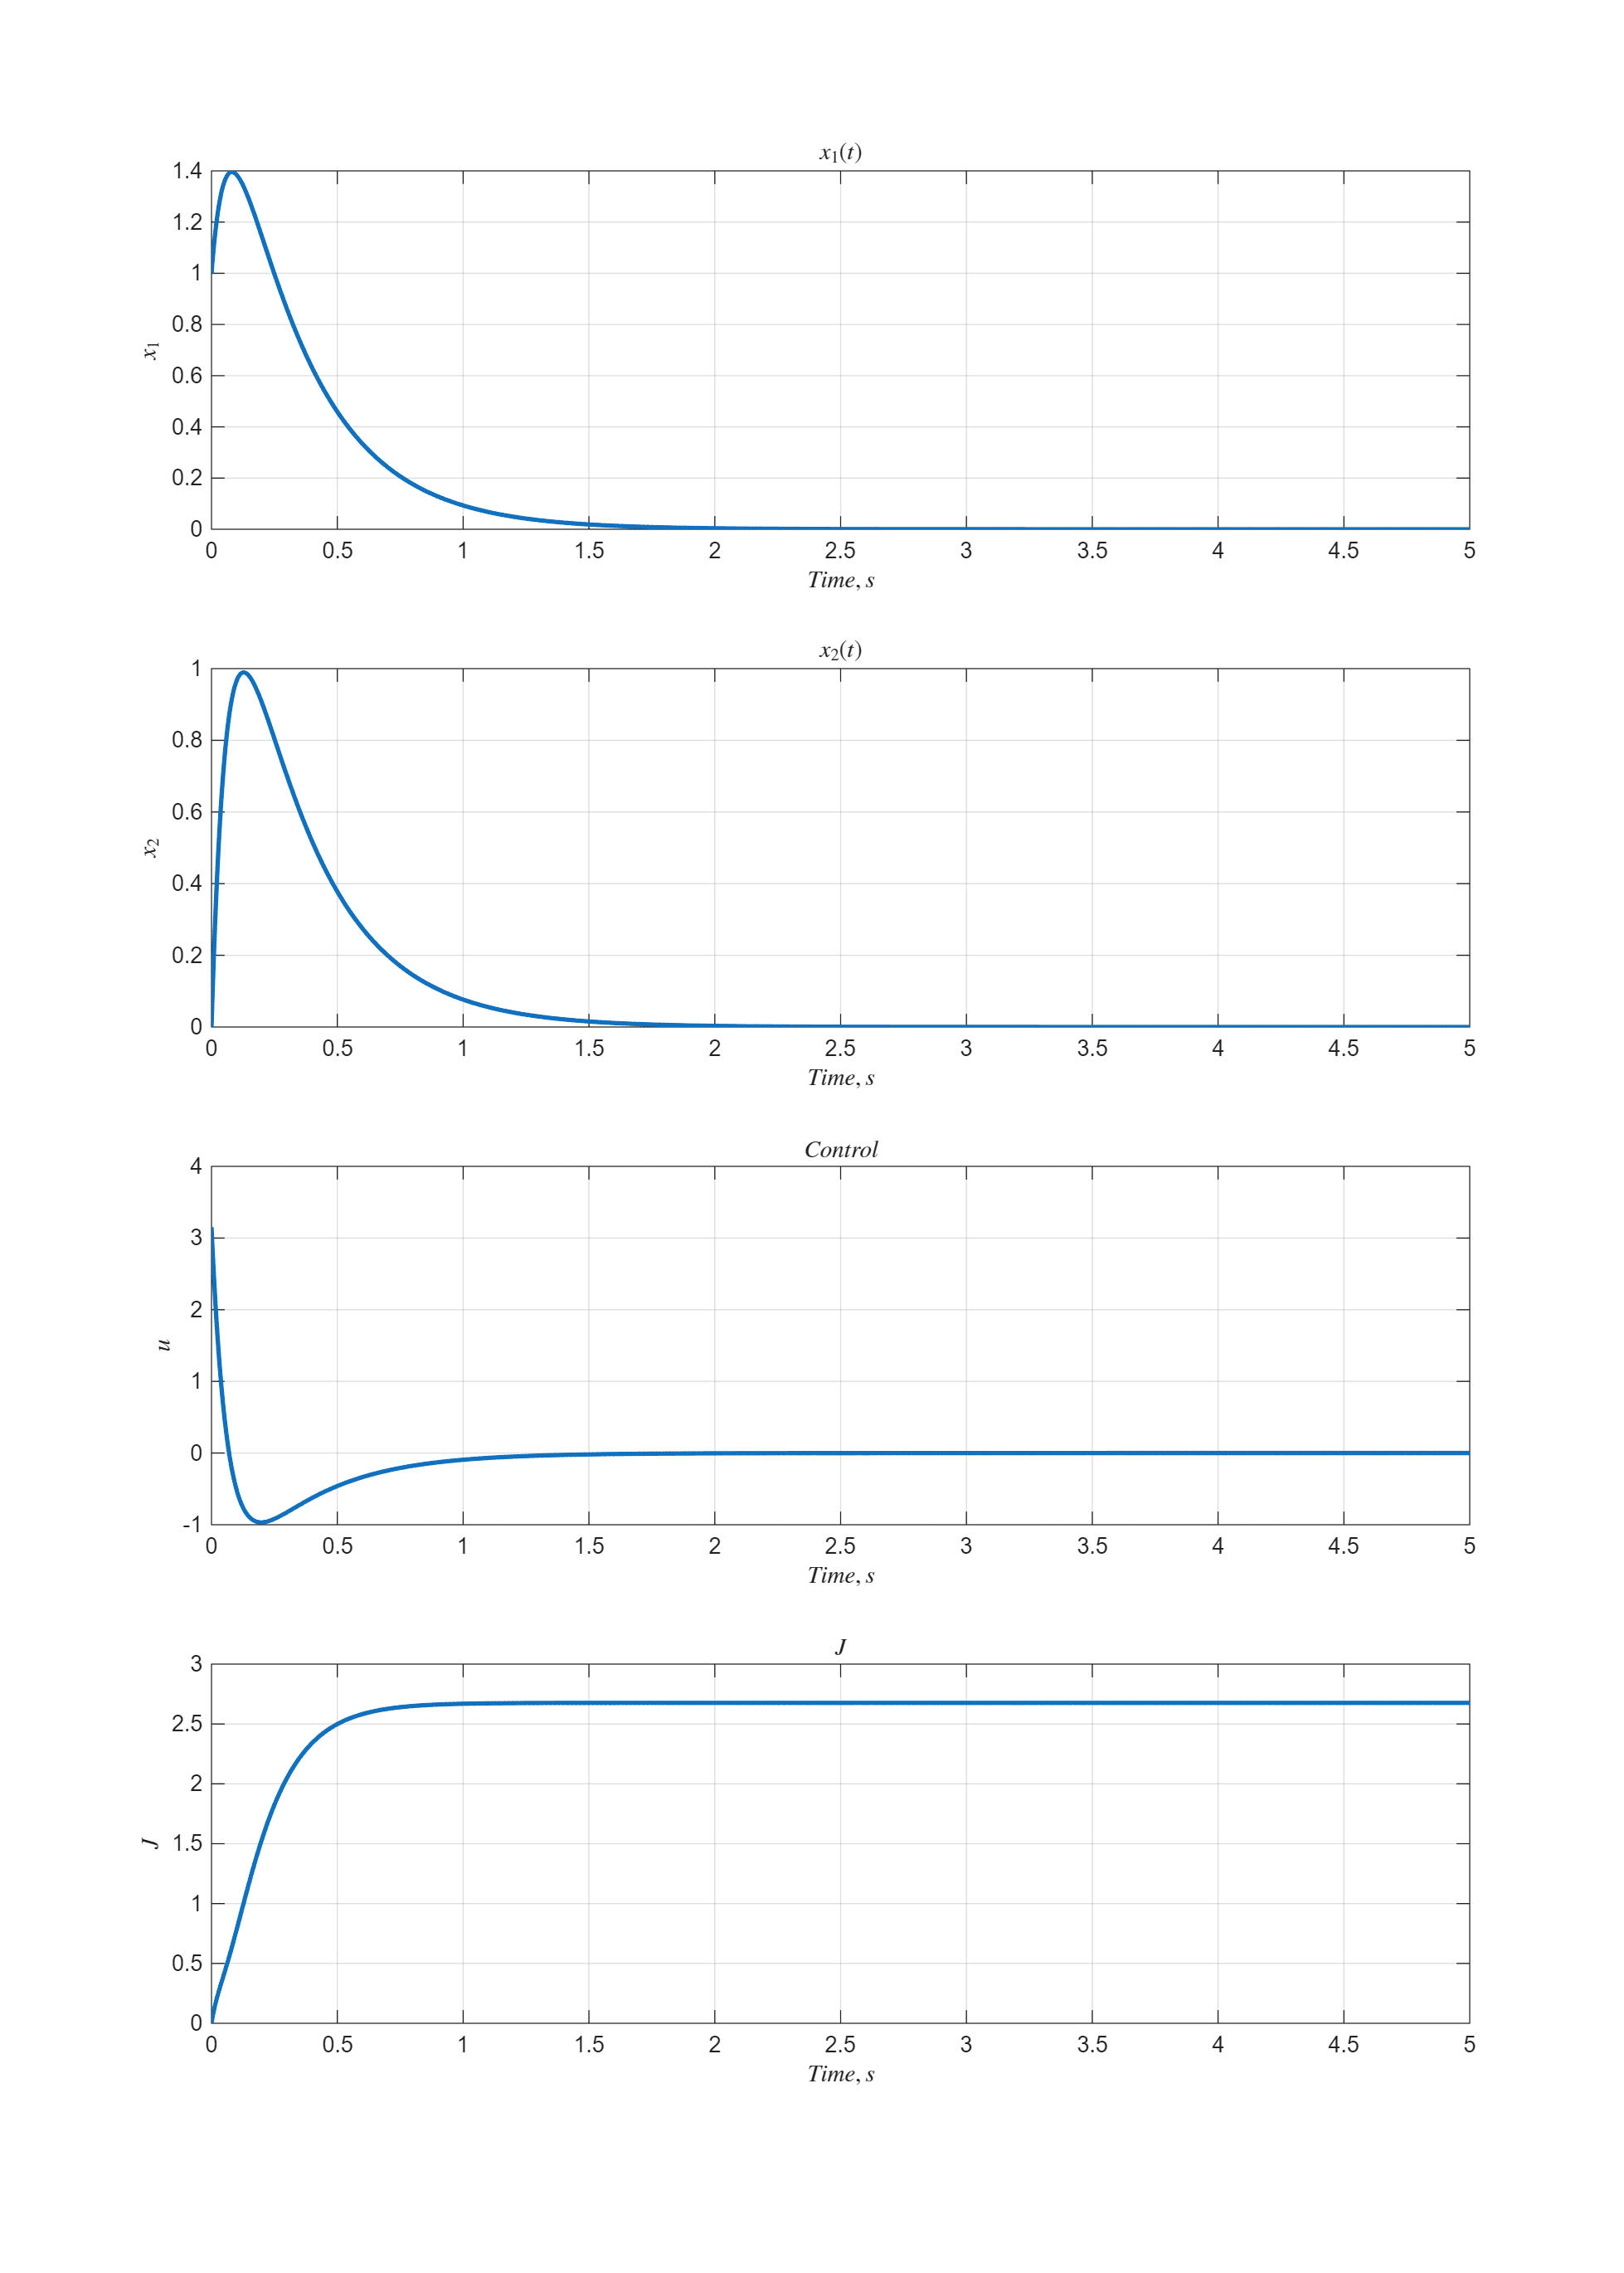


out = results{3};

fig = figure;
fig.Position = [100 100 1000 1400];

subplot(4,1,1);
plot(out.t, out.X(:,1), LineWidth=2);
title("$x_1(t)$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$x_1$", Interpreter="latex");
grid("on");

subplot(4,1,2);
plot(out.t, out.X(:,2), LineWidth=2);
title("$x_2(t)$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$x_2$", Interpreter="latex");
grid("on");

subplot(4,1,3);
plot(out.t, out.u, LineWidth=2);
title("$Control$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$u$", Interpreter="latex");
grid("on");

subplot(4,1,4);
plot(out.t, out.J, LineWidth=2);
title("$J$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$J$", Interpreter="latex");
grid("on");

exportgraphics(fig, fullfile(folder, "task4.png"), Resolution=600);

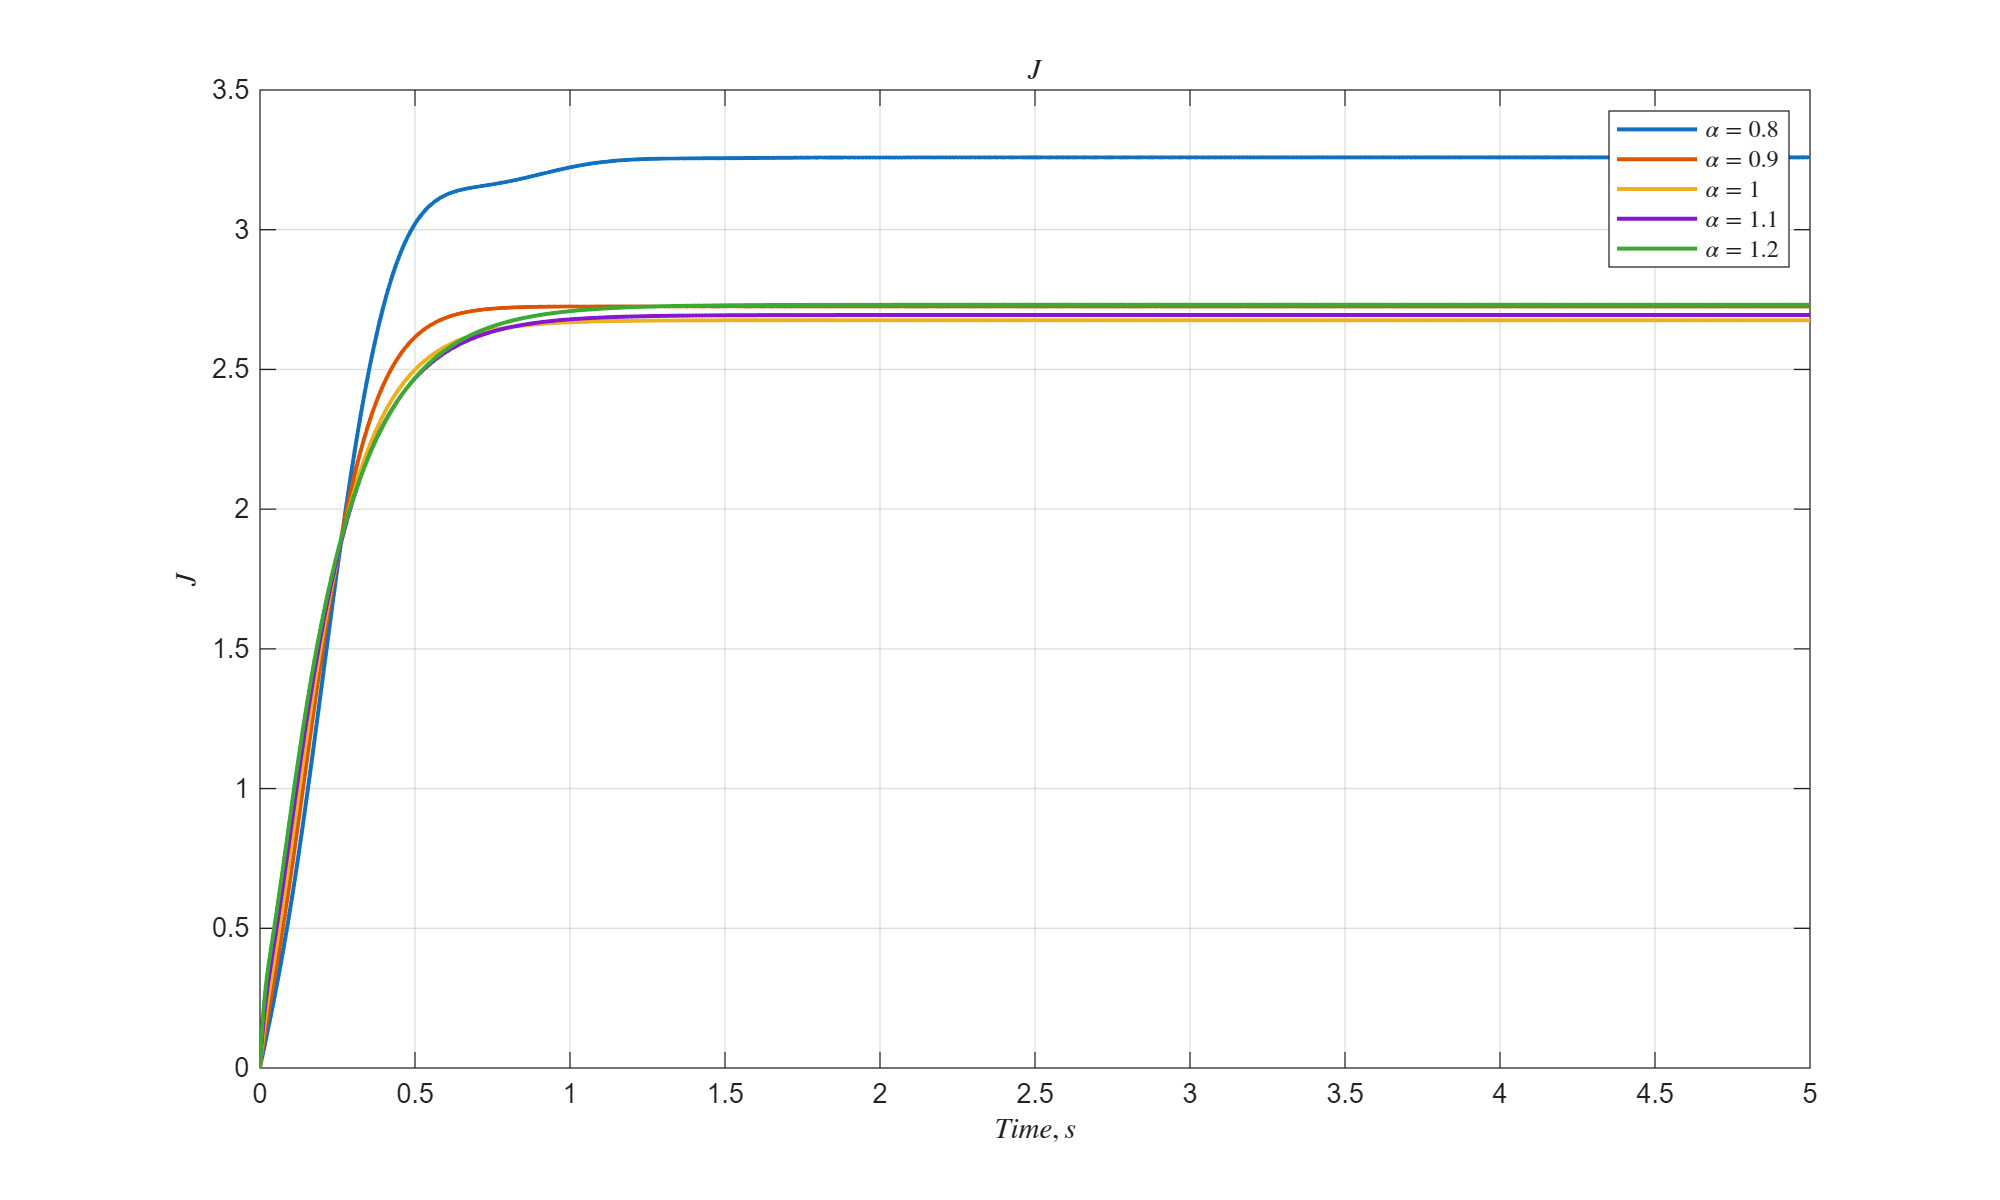


fig = figure;
fig.Position = [100 100 1000 600];

for i = 1:5
    plot(results{i}.t, results{i}.J, LineWidth=1.5);
    hold on;
end

title("$J$", Interpreter="latex");
xlabel("$Time, s$", Interpreter="latex");
ylabel("$J$", Interpreter="latex");
legend({"$\alpha=0.8$", "$\alpha=0.9$", ...
        "$\alpha=1$", "$\alpha=1.1$", ...
        "$\alpha=1.2$"}, Interpreter="latex");
grid("on");

exportgraphics(fig, fullfile(folder, "task4_compare.png"), Resolution=600);



function dp = riccati(t,p,A,B,Q,r)
    P = [p(1) p(2); p(2) p(3)];

    dP = -(A.'*P + P*A + Q - P*B*(B.'*P)/r);

    dp = [dP(1,1); dP(1,2); dP(2,2)];
end

function dx = model(t,x,solP,A,B,Q,r,alpha)
    p = deval(solP,t);
    P = [p(1) p(2); p(2) p(3)];

    K = B.'*P/r;
    u = -alpha*K*x(1:2);

    dx = [
        A*x(1:2) + B*u;
        x(1:2).'*Q*x(1:2) + r*u^2
    ];
end
